# Actividad 4.1 (Evaluación)

**Implementar** el código requerido para generar las siguientes trayectorias a partir de las velocidades angulares y lineales en un plano 2D.

**Trayectoria 1:**

**x= [0 a 10]**

**f(x) = 2*sen(****x****)*e^(-0.3*x)**

1. Definimos la función de la trayectoria a parametrizar.

2. Realizamos la paramterízación de las funciones respecto al tiempo:

    **x(t)=t**

    **y(t)=2*sen(t)*e^(-0.3*t)**

      3. Calculamos las derivadas de las funciones para obtener las velocidades en cada eje:

    **x ̇(t)=1**

**    y ̇(t)=-0.6*sen(t)*e^(-0.3*t) + 2*cos(t)*e^(.0.3*t) **

      4. Obtenemos la expresión matemática para la velocidad lineal **u(t): u(t)=√(1+(-0.6*sen(t)*e^(-0.3*t) + 2*cos(t)*e^(.0.3*t))^2 )**

5. Calculamos la expresión del ángulo de orientación **θ(t) y **6. Obtenemos la expresión matemática para la velocidad angular **ω(t).**

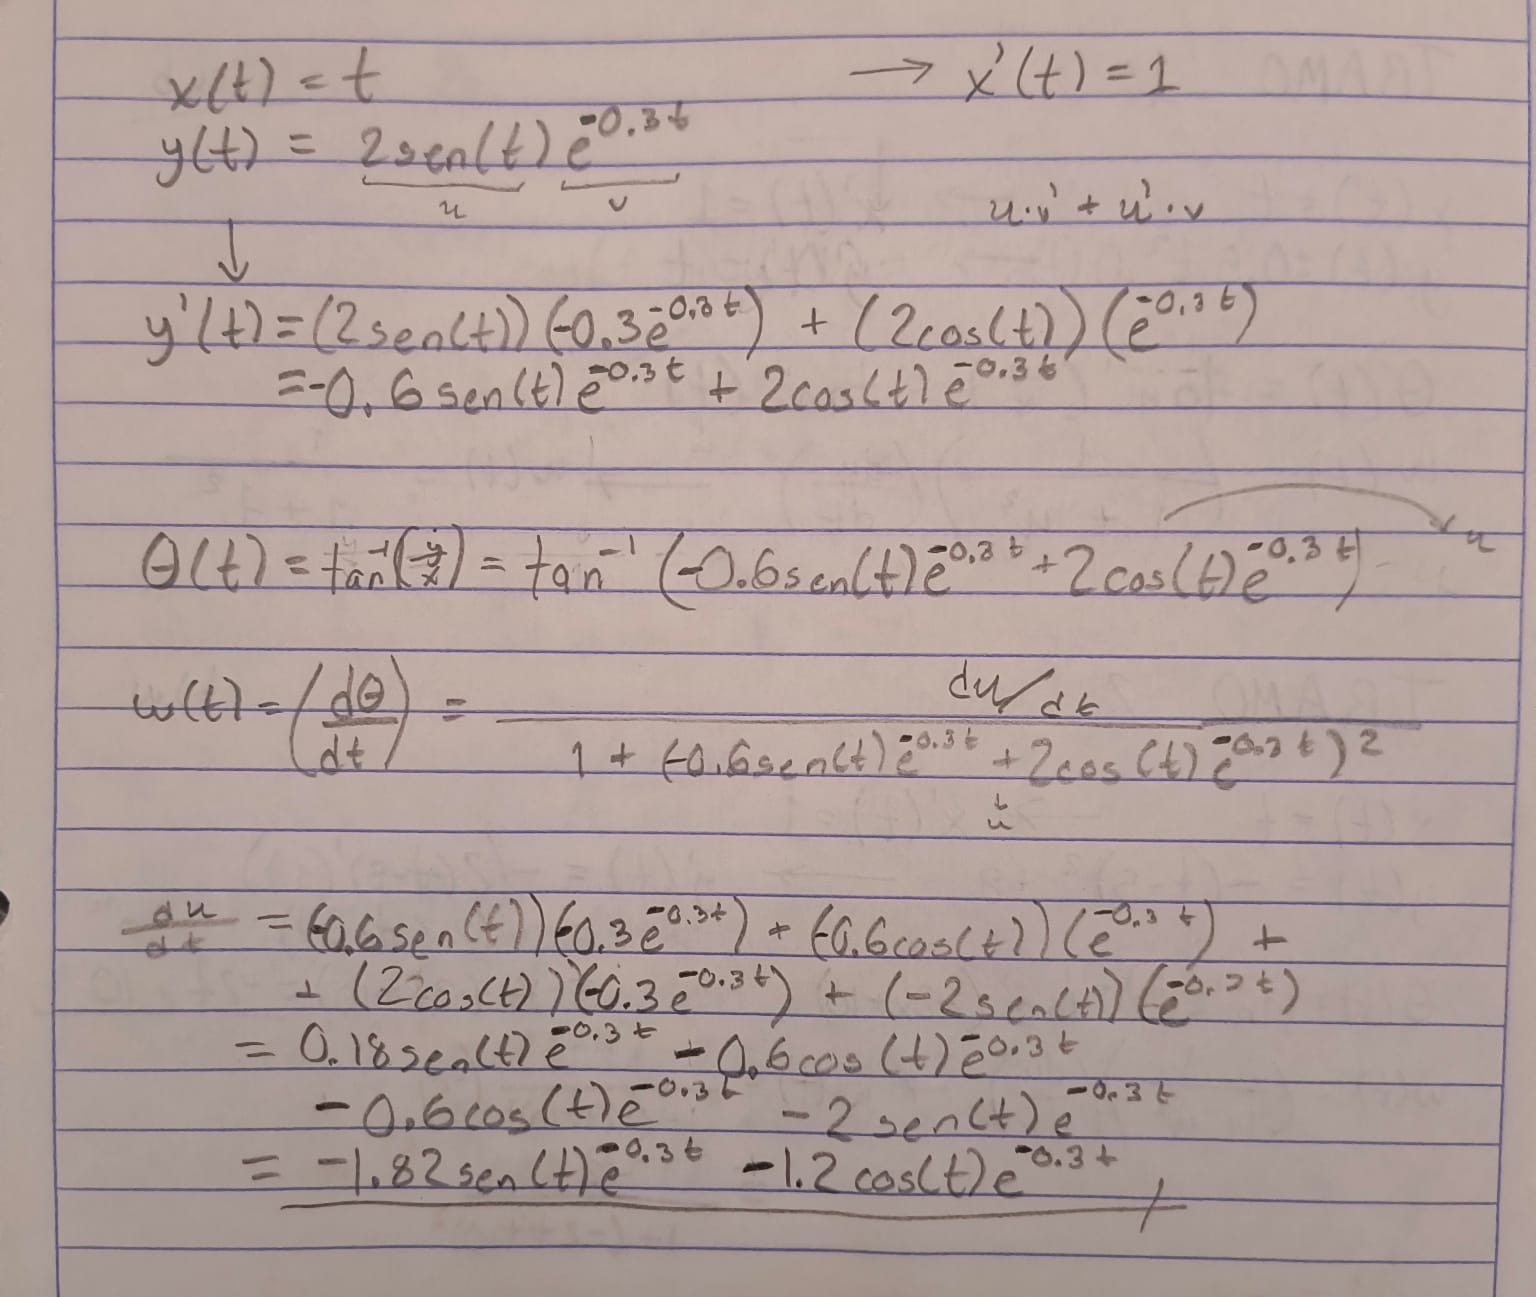

7. Finalmente obtenemos la expresión matemática para la velocidad lineal **u(t)** y la velocidad angular **ω(t)**.

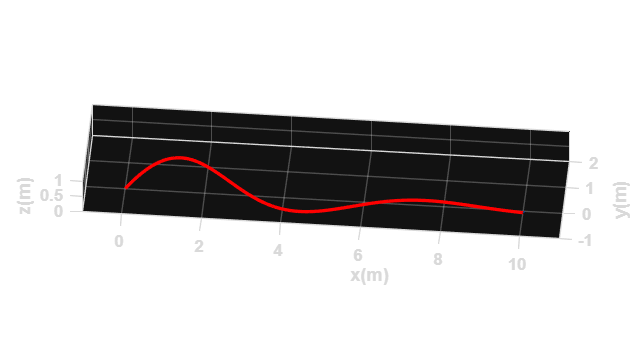

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 10;              % Tiempo de simulacion en segundos (s)
ts = 0.01;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

% Condiciones de la trayectoria específicas
x1(1) = 0;              
y1(1) = 0;              
phi(1) = atan((2*sin(ts)*exp(-0.3*ts))/ts);       

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N); % velocidad lineal
w = zeros(1,N); % velocidad angular

for k = 1:N
    
    tk = t(k);
    
    dx = 1;
    dy = -0.6*sin(tk)*exp(-0.3*tk) + 2*cos(tk)*exp(-0.3*tk);
    
    % Velocidad lineal
    u(k) = sqrt(dx^2 + dy^2);
    
    % Velocidad angular
    w(k) = (-1.82*sin(tk)*exp(-0.3*tk) - 1.2*cos(tk)*exp(-0.3*tk)) / (1 + (dy)^2);
    
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    %Aplicamos el modelo cinemático diferencial para obtener las
    %velocidades en x, y, phi
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    phip= w(k);

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([5 40]); % Orientacion de la figura
axis([-1 11 -1 2 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 0.5;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

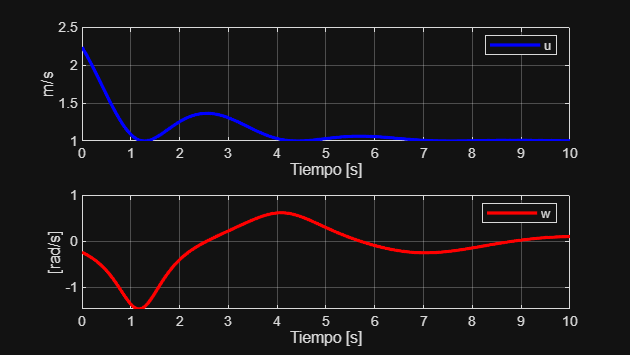


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

**Trayectoria 2**

Para cada parte de la función a trozos, es necesario realizar el proceso de paramaterízación en seguimiento de trayectorias:

- **Tramo 1**

                1. Definimos la función de la trayectoria a parametrizar.

                2. Realizamos la paramterízación de las funciones respecto al tiempo:

                    **x(t)=t**

                    **y(t)=0.5*t^2**

                3. Calculamos las derivadas de las funciones para obtener las velocidades en cada eje:

                    **x ̇(t)=1**

**                    y ̇(t)=t**

                4. Obtenemos la expresión matemática para la velocidad lineal **u(t): u(t)=√(1+(t)^2 )**

                5. Calculamos la expresión del ángulo de orientación **θ(t) y **6. Obtenemos la expresión matemática para la velocidad angular **ω(t).**

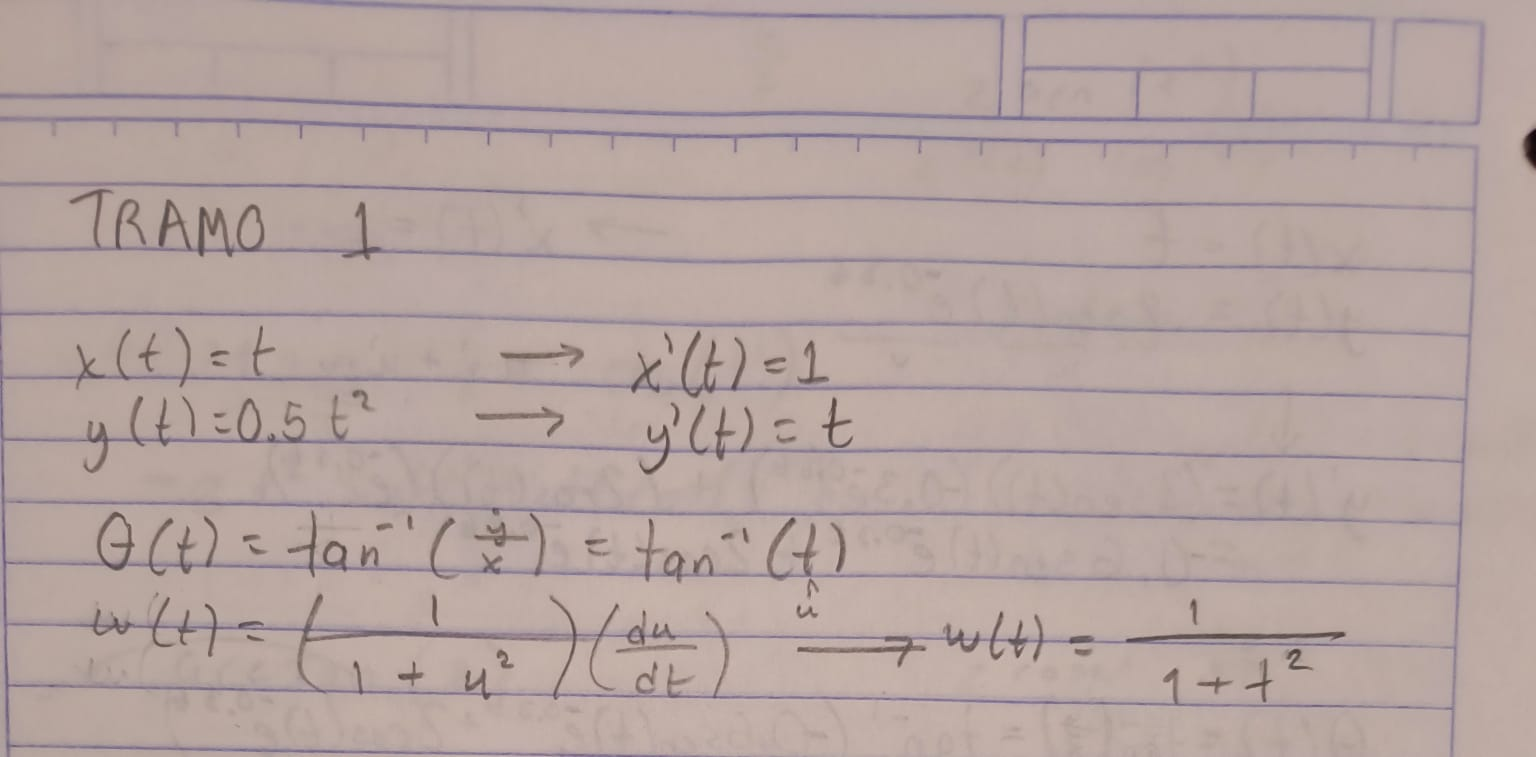

                7. Finalmente obtenemos la expresión matemática para la velocidad lineal **u(t)** y la velocidad angular **ω(t)**.

- **Tramo 2**

                1. Definimos la función de la trayectoria a parametrizar.

                2. Realizamos la paramterízación de las funciones respecto al tiempo:

                    **x(t)=t**

                    **y(t)=-(t-5)^2 + 8**

                3. Calculamos las derivadas de las funciones para obtener las velocidades en cada eje:

                    **x ̇(t)=1**

**                    y ̇(t)= -2t + 10**

                4. Obtenemos la expresión matemática para la velocidad lineal **u(t): u(t)=√(1+(-2t + 10)^2 )**

                5. Calculamos la expresión del ángulo de orientación **θ(t) y **6. Obtenemos la expresión matemática para la velocidad angular **ω(t).**

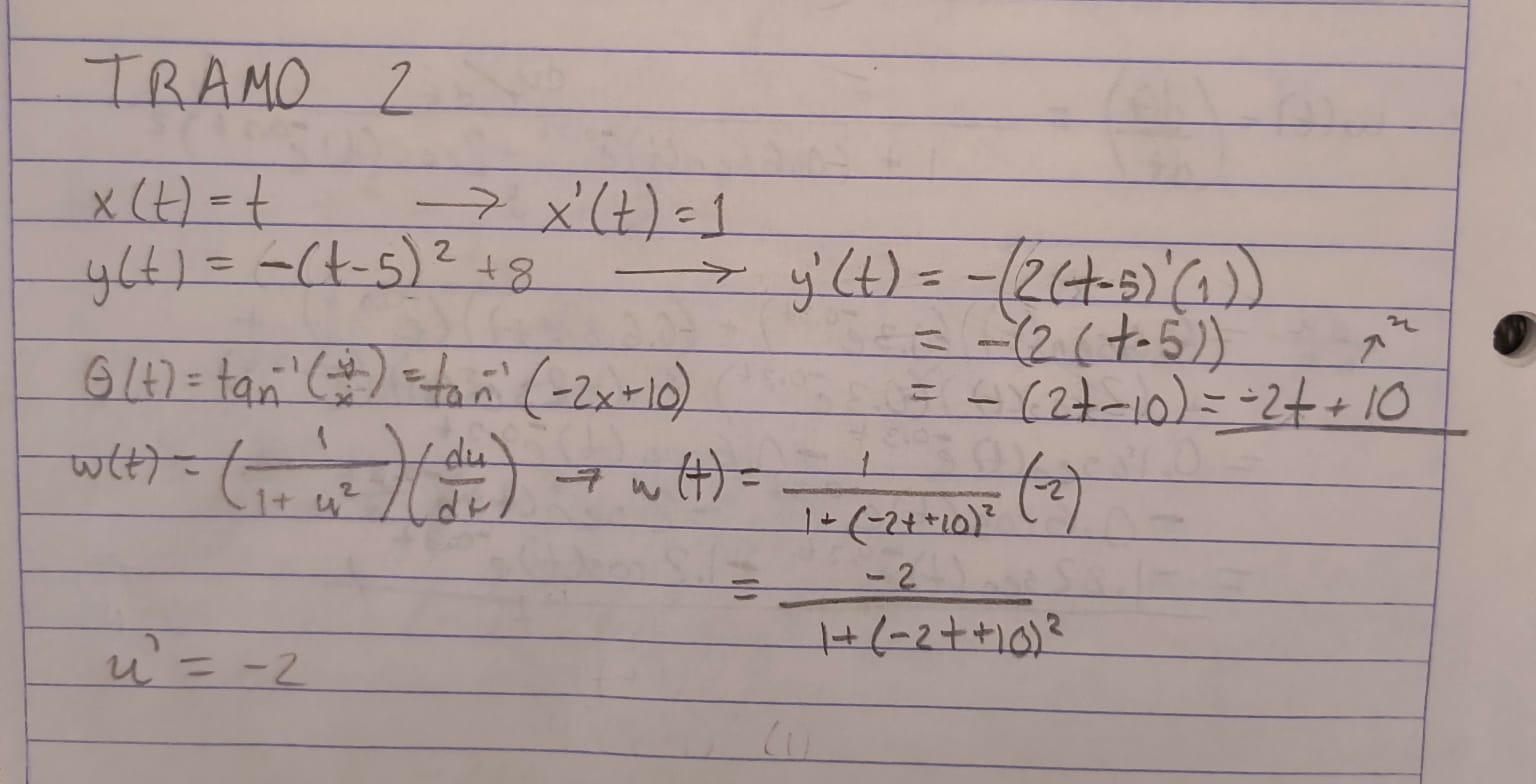

                7. Finalmente obtenemos la expresión matemática para la velocidad lineal **u(t)** y la velocidad angular **ω(t)**.

- **Tramo 3**

                1. Definimos la función de la trayectoria a parametrizar.

                2. Realizamos la paramterízación de las funciones respecto al tiempo:

                    **x(t)=t**

                    **y(t)=2*e^(t-7)*cos(t-7)**

                3. Calculamos las derivadas de las funciones para obtener las velocidades en cada eje:

                    **x ̇(t)=t**

**                    y ̇(t)= -2*e^(t-7)*sin(t-7) + 2*e^(t-7)*cos(t-7)**

                4. Obtenemos la expresión matemática para la velocidad lineal **u(t): u(t)=√(1+(-2*e^(t-7)*sin(t-7) + 2*e^(t-7)*cos(t-7))^2 )**

                5. Calculamos la expresión del ángulo de orientación **θ(t) y **6. Obtenemos la expresión matemática para la velocidad angular **ω(t).**

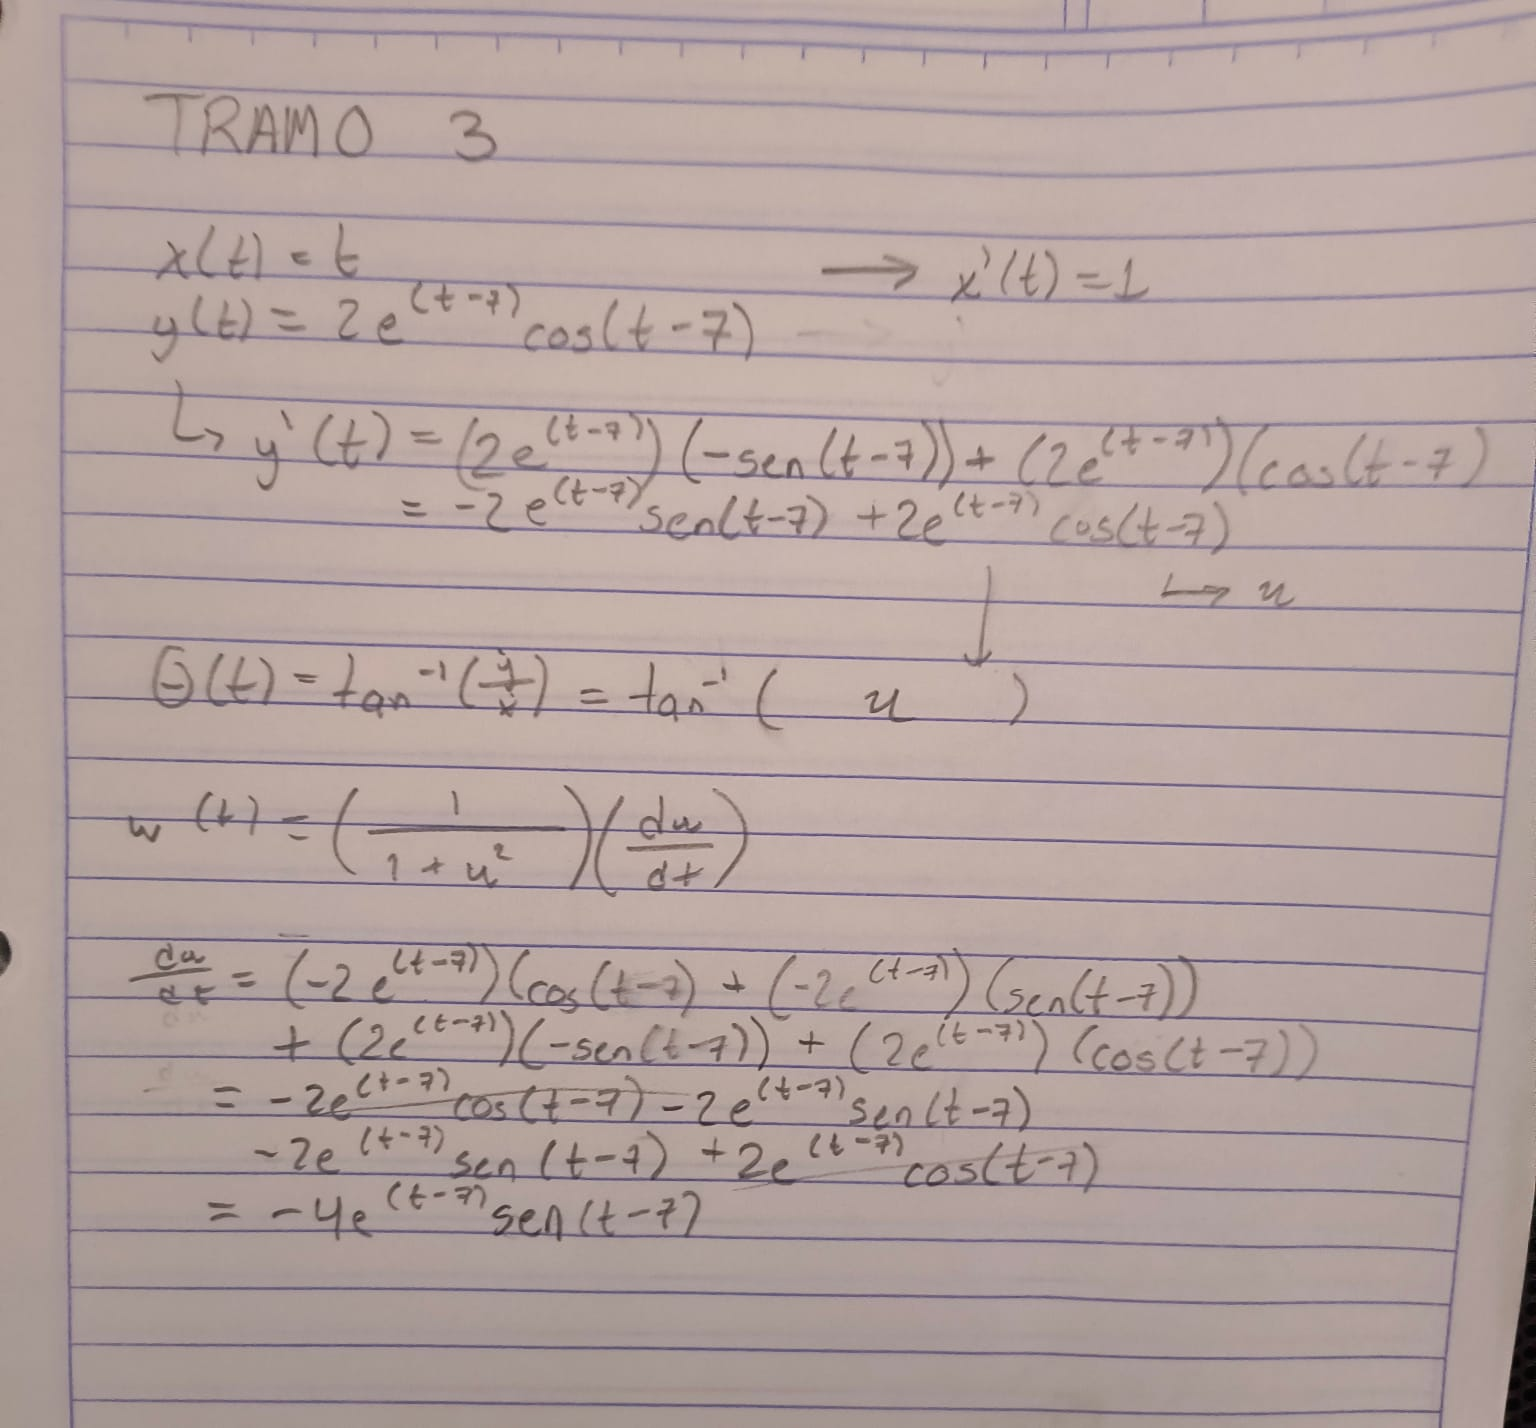

                7. Finalmente obtenemos la expresión matemática para la velocidad lineal **u(t)** y la velocidad angular **ω(t)**.

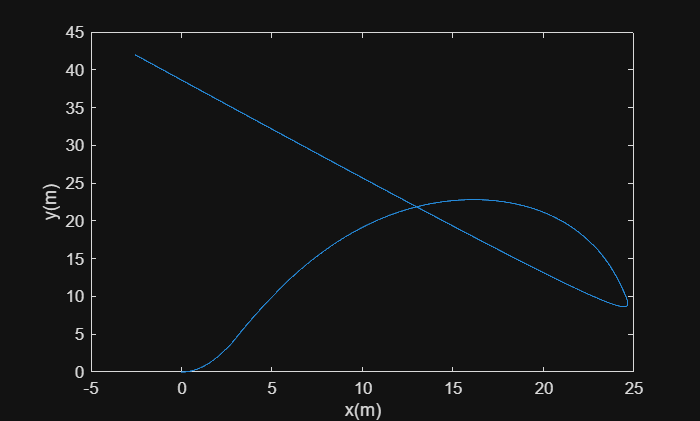

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
             
tf = 10;              % Tiempo de simulacion en segundos (s)
ts = 0.0000005;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras      

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

x1(1) = 0;              
y1(1) = 0;              
phi(1) = atan((0.5*(ts^2)) / ts);             

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N); 
w = zeros(1,N); 

for k = 1:N
    
    tk = t(k);
    
    % -------- TRAMO 1 --------
    % % %Función y(t)=0.5*t^2
    % t=[0, 3)

    if tk < 3
        
        dx = 1;
        dy = tk;
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = ( 1 / (1+tk^2) );
        
            
        % -------- TRAMO 2 --------
        %Función y(t)=-(t-5)^2 + 8
        % t=[3, 7)

    elseif tk < 7
        
        dx = 1;
        dy = -2*(tk-5) + 10;
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = ( (-2) / (1+(-2*tk+10)^2) );
        
            
        % -------- TRAMO 3 --------
        %Función y(t)=2*e^(t-7)*cos(t-7)
        % t=[7, 10]

    else

        dx = 1;
        dy = -2*exp(tk-7)*sin(tk-7) + 2*exp(tk-7)*cos(tk-7);
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = ( (-4*exp(tk-7)*sin(tk-7)) / (1+(dy)^2) );
        
    end
    
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts;
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts; 
    y1(k+1)=y1(k) + yp1*ts; 
    
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% scene=figure;
% set(scene,'Color','white');
% set(gca,'FontWeight','bold');
% sizeScreen=get(0,'ScreenSize');
% set(scene,'position',sizeScreen);
% camlight('headlight');
% axis equal;
% grid on;
% box on;
% xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
% 
% view([5 40]);
% axis([-1 9 -75 10 0 1]);
% 
% scale = 0.5;
% MobileRobot_5;
% H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;
% 
% H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
% 
% step=1;
% 
% for k=1:step:N
% 
%     delete(H1);    
%     delete(H2);
% 
%     H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
%     H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
% 
%     pause(ts);
% 
% end
figure;
plot(x1, y1)
xlabel('x(m)'); ylabel('y(m)');



%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%

graph=figure;
set(graph,'position');

  0×0 empty cell array



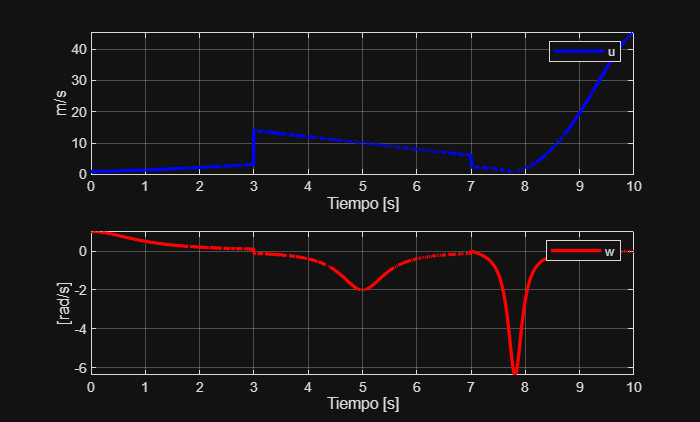


subplot(211)
plot(t,u,'b','LineWidth',2),grid on
xlabel('Tiempo [s]'),ylabel('m/s'),legend('u')

subplot(212)
plot(t,w,'r','LineWidth',2),grid on
xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w')